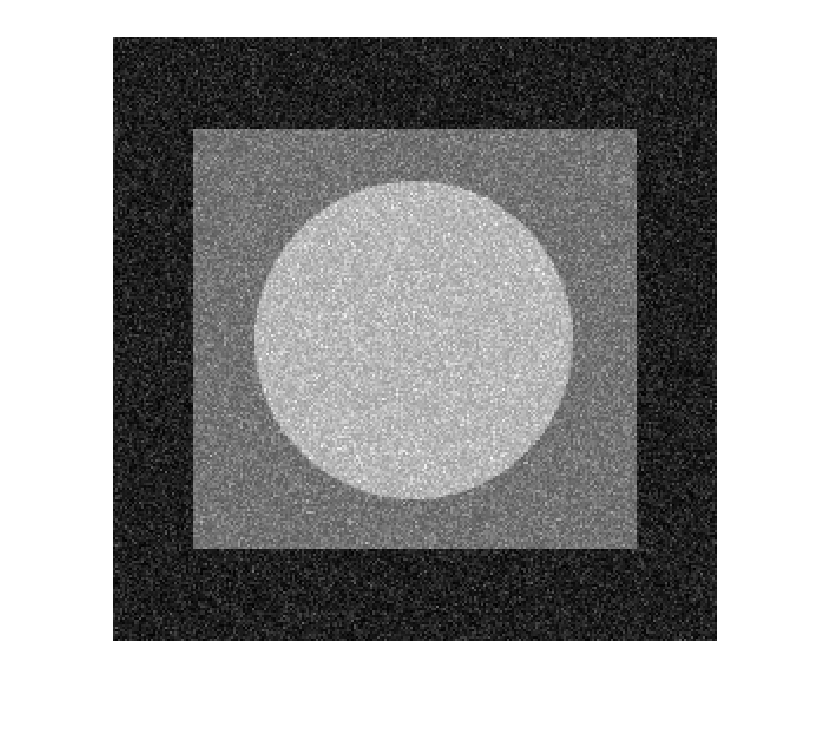

clear all;
close all;
clc;

%Zoom Exercise
T = im2double(imread('test-pattern1.tif'));
M = size(T,1);
N = size(T,2);
TN = zeros([M,N]);
imshow(T);

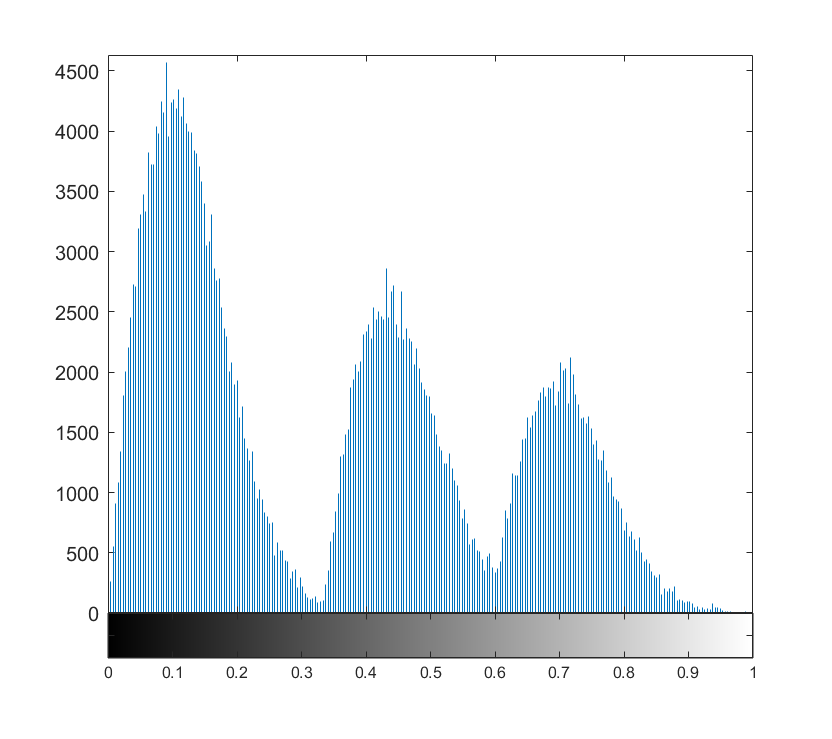

imhist(T);

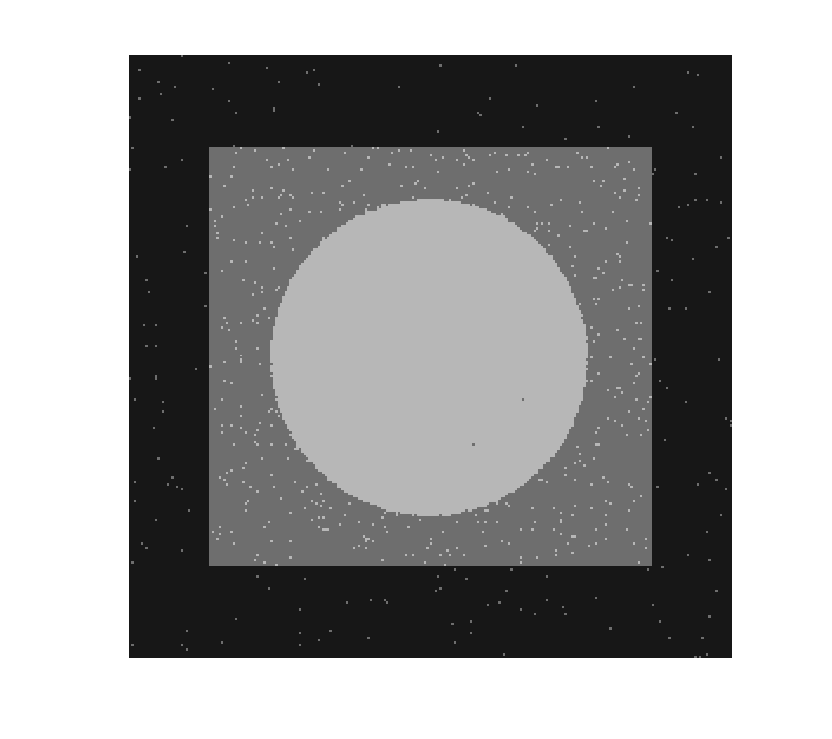

[counts,L] = imhist(T);
M = size(T,1);
N = size(T,2);
k = 1/25 * [1,1,1,1,1;
           1,1,1,1,1;
           1,1,1,1,1;
           1,1,1,1,1;
           1,1,1,1,1]; %average kernel
peak1 = max(counts(1:84));
peak2 = max(counts(85:150));
peak3 = max(counts(151:256));
l1 = find(counts(1:84) == peak1);
l2 = find(counts(85:150) == peak2) + 84;
l3 = find(counts(151:256) == peak3) + 150;

L1 = L(l1);
L2 = L(l2);
L3 = L(l3);
for r = 1:M
    for c = 1:N
        if T(r,c) <= .32
             TN(r,c) = L1;
        elseif T(r,c) <= 0.6
            TN(r,c) = L2;
        else
            TN(r,c) = L3;
        end
    end
end

imshow(TN)

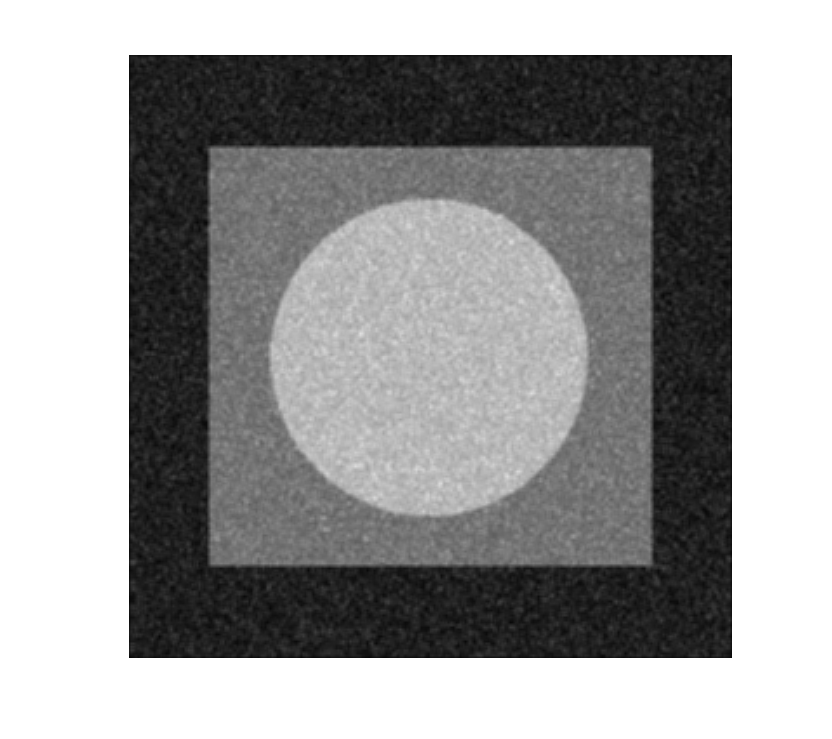


averg = conv2(T,k,"same"); %auto-removes excess boarders
imshow(averg);

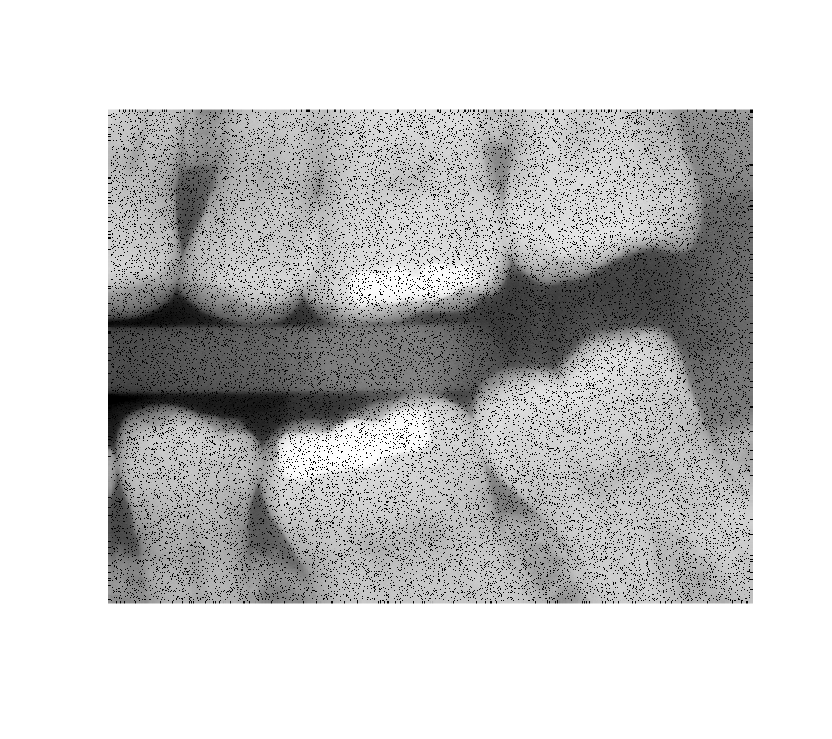


D = im2double(imread('dentalXray.tif')); 
imshow(D);

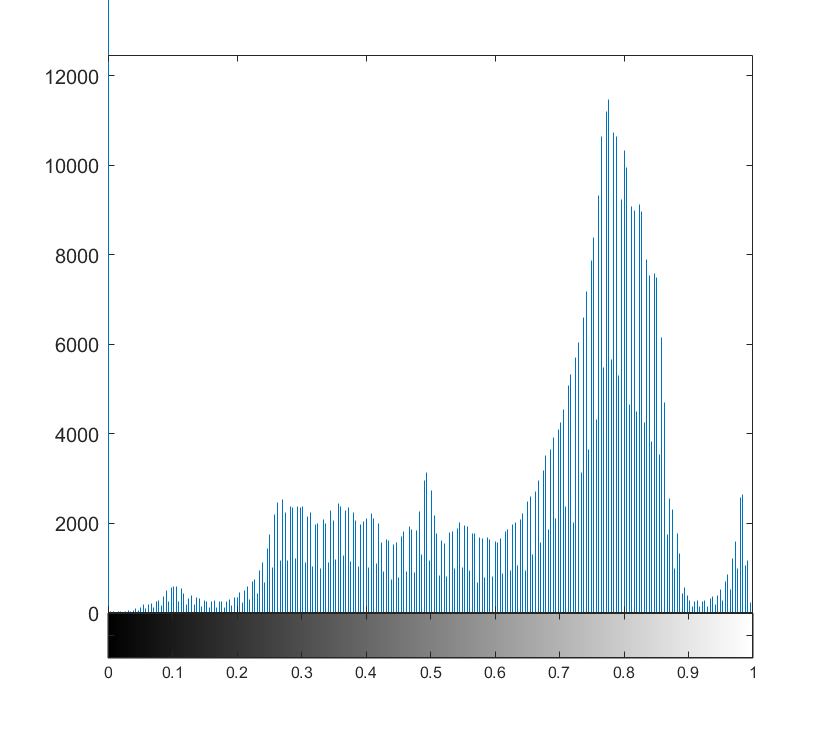

imhist(D);

% 

% dist = zeros(M,N);
% filter = ones(M,N);
% 
% filter(1:1:170,290:1:334) = 0;
% filter(1:1:170,342:1:386) = 0;
% filter(505:1:662,290:1:334) = 0;
% filter(505:1:662,342:1:386) = 0;
% 
% imshow(filter);
% 
% imshow(T); title('Original');
% 
% TZfft = fft2(T);
% TZfft2 = fftshift(TZfft);
% 
% TZfft3 = log(abs(TZfft2)+1); %abs and + 1 for display
% disp_fft = mat2gray(TZfft3); 
% imshow(disp_fft); title('Magnitude of Shifted FFT on Log Scale');
% 
% imshow(filter); title('Ideal Low Pass Filter');
% 
% Tlp = TZfft2 .* filter;
% mod = log(abs(Tlp)+1);
% imshow(mat2gray(mod));
% Tlp2 = ifftshift(Tlp);
% Tlp3 = abs(ifft2(Tlp2));
% TLowPass = Tlp3(1:M,1:N);
% imshow(TLowPass); title('Ideal Low Pass Filter Applied');
% 